%hola
clear; clc; close all;

% PARAMETERS (Slide 37)
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-6; % Time step (must be small!)
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.01; % Mitral resistance
Rao = 0.01; % Aortic resistance
Rs  = 17.5; % Systemic resistance
Csa = 0.001; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS
Psa(1) = 100;
Plv(1) = 5;

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);

function C = compute_dynamic_compliance(t, T, ts, tauS, tauD, Csystolic, Cdiastolic)
    % slide 30 eq
    tc = mod(t, T); % Time within cardiac cycle
    
    % Precompute denominators
    denom_systole = 1 - exp(-ts/tauS);
    denom_diastole = 1 - exp(-(T-ts)/tauD);
    
    % Systole phase (0 ≤ tc ≤ ts)
    in_systole = tc <= ts;
    e_sys = (1 - exp(-tc(in_systole)/tauS))./ denom_systole;
    C_sys = Cdiastolic * (Csystolic / Cdiastolic).^e_sys;
    
    % Diastole phase (ts < tc < T)
    in_diastole = tc > ts;
    e_dia = (1 - exp(-(tc(in_diastole) - ts)/tauD)) ./ denom_diastole;
    C_dia = Csystolic * (Cdiastolic / Csystolic).^e_dia;
    
    % Combine results
    C = zeros(size(t));
    C(in_systole) = C_sys;
    C(in_diastole) = C_dia;
end

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CLV(t(k));
    Clv_next = CLV(t(k+1));
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs;
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1200 700]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); grid on;
title('Systemic Arterial Pressure'); ylabel('mmHg');

subplot(2,3,2); plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); grid on;
title('Left Ventricular Pressure'); ylabel('mmHg');

subplot(2,3,3); plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); grid on;
title('Left Ventricular Volume'); ylabel('mL');

subplot(2,3,4); plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); grid on;
title('Mitral Flow');

subplot(2,3,5); plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); grid on;
title('Aortic Flow (Cardiac Output)');

subplot(2,3,6); plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); grid on;
title('LV Pressure-Volume Loop'); xlabel('Volume (mL)'); ylabel('Pressure (mmHg)');

% RESULTS
fprintf('Left Heart Model - Steady State:\n');

Left Heart Model - Steady State:


fprintf('Mean Arterial Pressure: %.1f mmHg\n', mean(Psa(end-5000:end)));

Mean Arterial Pressure: 81.7 mmHg


fprintf('LV Peak Pressure:%.1f mmHg\n', max(Plv(end-5000:end)));

LV Peak Pressure:6.8 mmHg


fprintf('Stroke Volume: %.1f mL\n',   max(Vlv(end-5000:end)*1000) - min(Vlv(end-5000:end)*1000));

Stroke Volume: 65.2 mL


fprintf('Cardiac Output: %.2f L/min\n', mean(valve_open(Plv, Psa) .* (Plv - Psa)/Rao));

Cardiac Output: 5.25 L/min


### Left Heart Model (NEW)

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.01; % Mitral resistance
Rao = 0.01; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);

function CV=CV_now(t,T,ts,tauS,tauD,CVS,CVD)
% Compliance of the Ventricle Testing
% CVS and CVD refer to the compliance of either the right or left
% ventricle during systole and diastole, respectively. CLVS, CRVS,
% CLVD, and CRVD.
% Remainder of cardiac cycle
tc=rem(t,T);
    for ii=1:length(tc) % For every time point that’s in tc
        if tc(ii)<ts % If tc is less than ts, systole
             e=(1-exp(-tc(ii)/tauS))/(1-exp(-ts/tauS));
             CV(ii)=CVD*(CVS/CVD)^e;
        else % If tc is greater than ts, diastole
             e=(1-exp(-(tc(ii)-ts)/tauD))/(1-exp(-(T-ts)/tauD));
             CV(ii)=CVS*(CVD/CVS)^e;
        end
    end
end

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');

## **Questions 6-7 can be solved using the Left Heart Model.**

• The Full Heart Model does not have a specific question but must be completed regardless. 

• Remember to start each question off from “baseline” healthy values for each model. Refer to the Parameters & Sources section of the “Cardiovascular Project Instructions Fall 2025” document for some details on how you can do this.

### Left Heart Model (NEW)

NORMAL

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.01; % Mitral resistance
Rao = 0.01; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 


% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');

## **Question 6: Valvular Heart Disease (Stenosis)**

**• Background:** Stenosis is a type of heart valve disease in which the valve opening becomes narrowed or stiffened, restricting the normal forward flow of blood. Instead of opening fully and allowing smooth passage, the thickened or calcified valve creates increased resistance that the heart must overcome to push blood through. This elevated workload can lead to pressure buildup, chamber hypertrophy, and eventually heart failure if untreated. Stenosis most commonly affects the elderly due to age-related calcific degeneration, though it can also result from rheumatic fever or congenital malformations. Because the valve tissue cannot be restored once significantly calcified or fibrotic, valve replacement surgery remains the primary and often only effective treatment for severe cases.

**• Task:** Using the Left Heart Model, simulate mitral and aortic stenosis by increasing the resistances `RMi` and `RAo`, respectively, enough to see a measurable change in the output graphs. Document the uncompensated effects on at least the left ventricular pressure (`PLV`), systemic arterial pressure (`Psa`), and stroke volume.

clear; clc; close all;
% RMi and RAo changed

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.5; % Mitral resistance
Rao = 0.5; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down);

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');
% entradndo y salinedo meonos sangre x calcuficacion, baj avolumen y sangre

## **Question 7: Valvular Heart Disease (Insufficiency)**

• Background: Insufficiency (regurgitation) occurs when a heart valve fails to close completely, allowing blood to leak backward through it when it should be sealed. Under normal conditions, heart valves act as one-way gates that maintain forward blood flow, but when their leaflets are damaged, deformed, or weakened due to causes such as rheumatic disease, infection, congenital malformation, or tissue degeneration, the valve cannot form a tight seal. This results in pathological backflow, forcing the heart to pump extra volume to maintain circulation, which can eventually cause chamber dilation, increased workload, and heart failure if left untreated.

• Task: Using the Left Heart Model, model valve leakage (insufficiency/regurgitation). For the mitral valve, modify its flow equation from `QMi` `=` `SMi` `*` `(Ppv` `-` `PLV)` `/` `RMi` to: `QMi` `=` `[SMi` `/` `RMiF` `+` `(1` `-` `SMi)` `/` `RMiB]` `*` `(Ppv` `-` `PLV) `where `RMiF` is the forward resistance (ideally 0 but usually small, i.e 0.01) and `RMiB` is the new, finite backflow resistance (ideally infinity but usually just very large, i.e 10000)). Apply a similar modification to the aortic valve (`RAoF` `and` `RAoB`). Investigate the hemodynamic consequences of reducing `RMiB` without altering `RAoB` and then vice versa. For a healthy mitral valve `RMiF` is very small and `RMiB` is very large, similar for the aortic valve.

% NORMAL HEART
clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

% NEW VALVE RESISTANCES
RMiF = 0.01; % Mitral forward resistance
RMiB = 10000; % Mitral backward resistance

Rmi = 0.5; % Mitral resistance
Rao = 0.5; % Aortic resistance
RAoF = 0.01; % Aortic forward resistance
RAoB = 10000; % Aortic backward resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance

% PREALLOCATE
Ppv = zeros(size(t)); Ppv(1) = 5;
Psa = zeros(size(t)); Psa(1) = 1000; % Modified IC
Plv = zeros(size(t)); Plv(1) = 50;
Vlv = zeros(size(t));

Qmi = zeros(size(t));
Qao = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now  = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv(k), Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows NEW
    Qmi(k) = ( S_mi / RMiF + (1 - S_mi) / RMiB ) * (Ppv(k) - Plv(k)); % Mitral
    Qao(k) = ( S_ao / RAoF + (1 - S_ao) / RAoB ) * (Plv(k) - Psa(k)); % Aortic
    Qs(k)  = Psa(k) / Rs; % Systemic (Assuming Psv << Psa)
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao(k) - Qs(k)) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi(k) - Qao(k))) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation – With Valve Regurgitation Model');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv(idx), Plv(idx)).* (Ppv(idx) - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');

% NEW CODE MICA 6/12 morning 
% Simulate aortic insufficiency (RAoB modified)

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

% NEW VALVE RESISTANCES
RMiF = 0.01; % Mitral forward resistance
RMiB = 1000; % Mitral backward resistance

Rmi = 0.5; % Mitral resistance
Rao = 0.5; % Aortic resistance
RAoF = 0.01; % Aortic forward resistance
RAoB = 50; % Aortic backward resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance

% PREALLOCATE
Ppv = zeros(size(t)); Ppv(1) = 5;
Psa = zeros(size(t)); Psa(1) = 1000; % Modified IC
Plv = zeros(size(t)); Plv(1) = 50;
Vlv = zeros(size(t));

Qmi = zeros(size(t));
Qao = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now  = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv(k), Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows NEW
    Qmi(k) = ( S_mi / RMiF + (1 - S_mi) / RMiB ) * (Ppv(k) - Plv(k)); % Mitral
    Qao(k) = ( S_ao / RAoF + (1 - S_ao) / RAoB ) * (Plv(k) - Psa(k)); % Aortic
    Qs(k)  = Psa(k) / Rs; % Systemic (Assuming Psv << Psa)
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao(k) - Qs(k)) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi(k) - Qao(k))) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation – With Valve Regurgitation Model');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv(idx), Plv(idx)).* (Ppv(idx) - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');

% NEW CODE MICA 6/12 morning 
% Simulate mitral insufficiency (RMiB changes)
clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

% NEW VALVE RESISTANCES
RMiF = 0.01; % Mitral forward resistance
RMiB = 50; % Mitral backward resistance

Rmi = 0.5; % Mitral resistance
Rao = 0.5; % Aortic resistance
RAoF = 0.01; % Aortic forward resistance
RAoB = 10000; % Aortic backward resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance

% PREALLOCATE
Ppv = zeros(size(t)); Ppv(1) = 5;
Psa = zeros(size(t)); Psa(1) = 1000; % Modified IC
Plv = zeros(size(t)); Plv(1) = 50;
Vlv = zeros(size(t));

Qmi = zeros(size(t));
Qao = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now  = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv(k), Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows NEW
    Qmi(k) = ( S_mi / RMiF + (1 - S_mi) / RMiB ) * (Ppv(k) - Plv(k)); % Mitral
    Qao(k) = ( S_ao / RAoF + (1 - S_ao) / RAoB ) * (Plv(k) - Psa(k)); % Aortic
    Qs(k)  = Psa(k) / Rs; % Systemic (Assuming Psv << Psa)
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao(k) - Qs(k)) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi(k) - Qao(k))) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation – With Valve Regurgitation Model');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv(idx), Plv(idx)).* (Ppv(idx) - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');


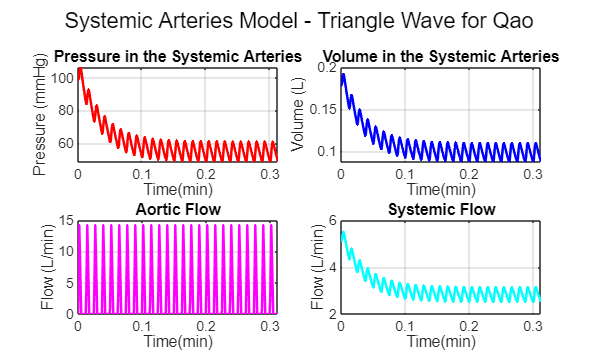

clear;clc;close all 

function Q=Qtriangwave(t,Qmax,T,ts,tmax)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 1e-6; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

## Question 1: The Aging Cardiovascular System 

- Background: Arteriosclerosis, or "hardening of the arteries," involves a reduction in arterial compliance. This decreased distensibility alters the relationship between blood volume and pressure in the arterial tree. 

- Task: Model arteriosclerosis by reducing the systemic arterial compliance parameter (C_sa) by a factor of 2 from your established baseline Systemic Arterial Model. Analyze and explain the resulting changes in systolic, diastolic, mean, and pulse pressures. 

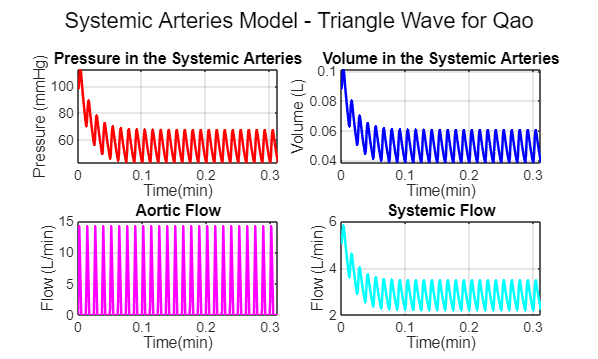

clear;clc;close all 

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 1e-6; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa = (0.0015*1.2)/2; % Compliance constant for systemic arteries (L/mmHg) reduced by a factor of 2
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

## Question 2: The Normal Hemodynamic Response to Exercise 

- Background: Exercise induces vasodilation in skeletal muscle by reducing systemic vascular resistance (R_s). To maintain blood pressure and increase delivery, cardiac output (CO) must rise, primarily through increased heart rate (HR). 

- Task: Simulate normal exercise using the Systemic Arterial Model. First, reduce R_s by a factor of 2. Then, double the heart rate by halving the cardiac cycle duration (T), systole duration (ts), and time to peak flow (tMAX). To maintain stroke volume (SV), you will need to adjust the peak aortic flow parameter (Qmax). Implement these changes and observe the new waveforms.

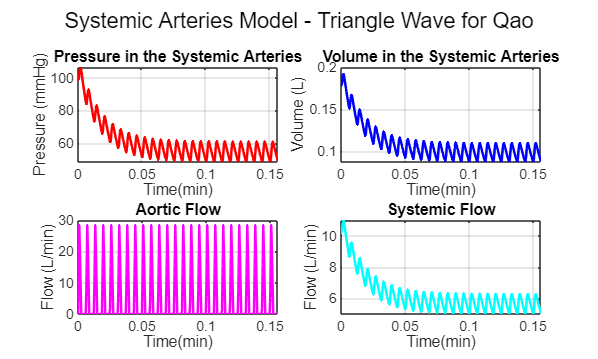

clear;clc;close all 

% Initial Parameters + Preallocating

T=0.0125/2; % Time for 1 heart beat (min) 
ts=0.0050/2;  % Time for systole (min) 
tmax= 0.002/2; % Time for max flow rate during systole (min) if using triangle wave 
dt = 1e-6; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = (17.5*1.107)/2 ; % Resistance of the systemic circuit (mmHg/(L/min)) reduced by a factor of 2
Qmax=14.14*2; % Max flow rate through aorta during systole (L/min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');